% Create a yagiUda antenna
% Generated by MATLAB(R) 23.2 and Antenna Toolbox 23.2.
% Generated on: 25-Nov-2023 19:29:09

## Antenna Properties

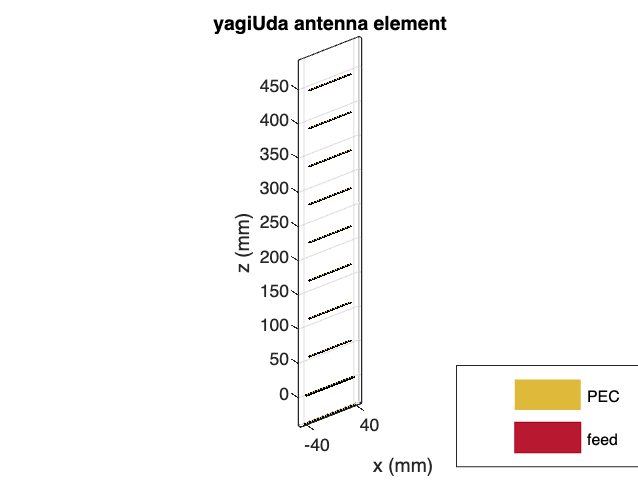

antennaObject = design(yagiUda, 1700*1e6);
antennaObject.Exciter= dipoleFolded;
antennaObject.Exciter.Length = 0.076853;
antennaObject.Exciter.Width = 0.0019575;
antennaObject.Exciter.Spacing = 0.0010052;
antennaObject.NumDirectors = 8;
% Show
figure;
show(antennaObject)

## Antenna Analysis

Define plot frequency 

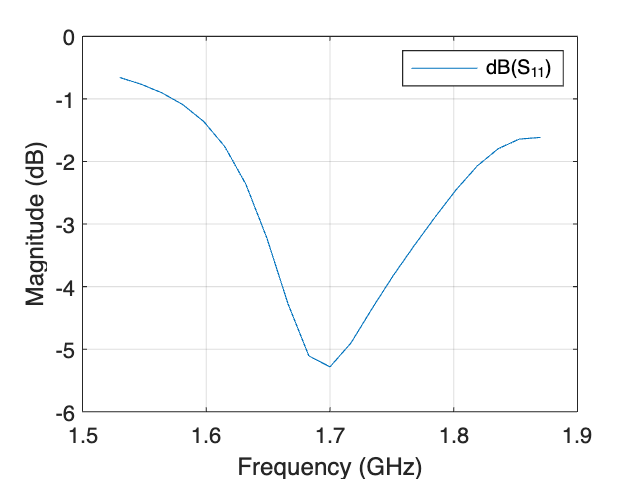

plotFrequency = 1700*1e6;
% Define frequency range 
freqRange = (1530:17:1870)*1e6;
% Reference Impedance 
refImpedance = 50;
% sparameter
figure;
s = sparameters(antennaObject, freqRange, refImpedance); 
rfplot(s)

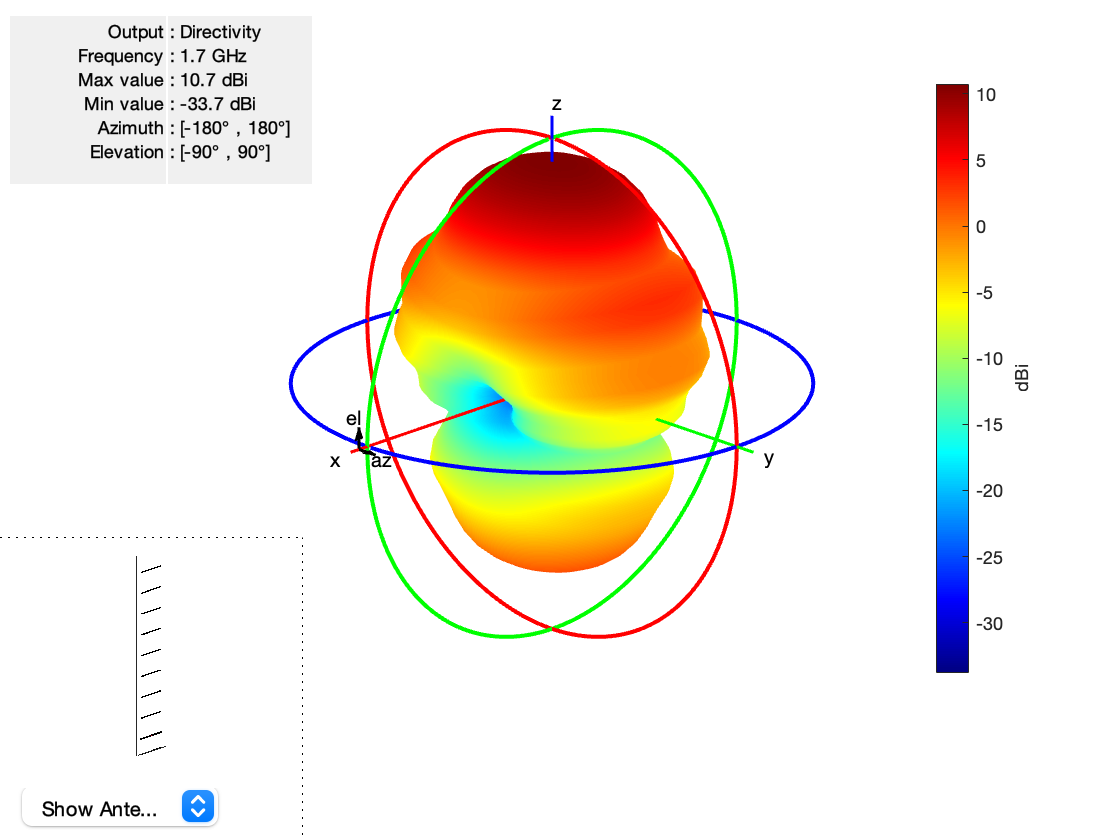

% pattern
figure;
pattern(antennaObject, plotFrequency)

% azimuth
figure;
Azfieldval = patternAzimuth(antennaObject, plotFrequency, 0, 'Azimuth', 0:5:360);
% elevation
figure;
Elfieldval = patternElevation(antennaObject, plotFrequency,0,'Elevation',0:5:360);